# Euler's method

## Introduction

In this activity we will learn how to implement Euler's method in MATLAB to numerically solve an ordinary differential equation given an initial value.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

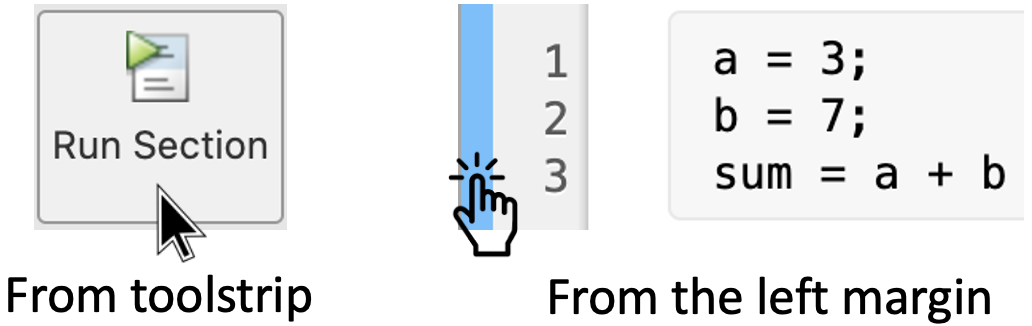

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Euler's method

**Euler's method** is one of the simplest numerical methods for approximating solutions of first-order initial-value problems

$\frac{dy}{dt}=f(t,y)$ with initial condition $y(t_0)=0$.

The idea behind this method is to find approximate values for the solution at equally spaced numbers


$$t_0, \;t_1=t_0+\Delta t, \;t_2=t_1+\Delta t, \;t_3=t_2+\Delta t, \ldots$$


where $\Delta t$ is the step size. The differential equation tells us that the slope at $(t_0,y_0)$ is 


$$\frac{dy}{dt}=f\left(t_0,y_0\right)$$


so the approximate value of the solution when $t=t_1$ is


$$y_1=y_0+\Delta t \,f\left(t_0,y_0\right)$$


as it is shown in the Figure below.

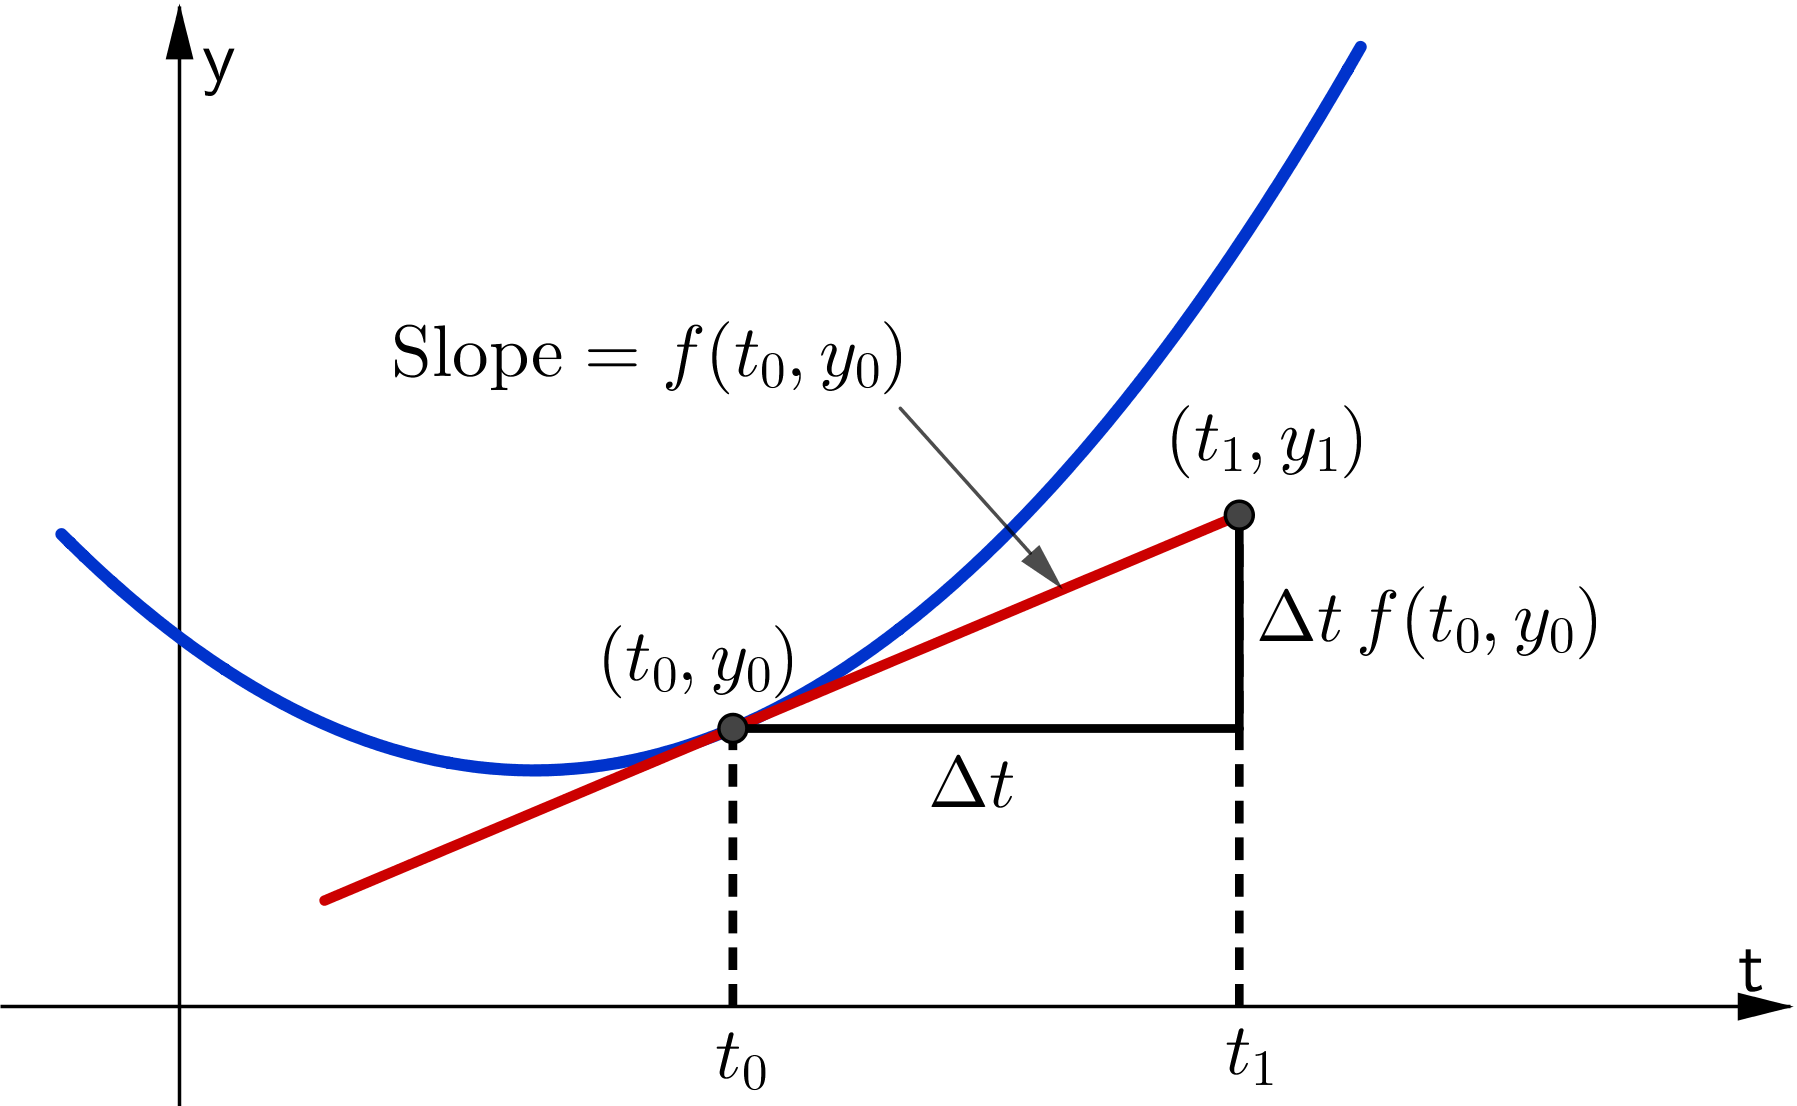

Similarly, we find that $y_2=y_1+\Delta t \,f\left(t_1,y_1\right)$. In general, we have

$y_k=y_{k-1}+\Delta t \,f\left(t_{k-1},y_{k-1}\right)$.

## 2 Basic example

### 2.1 How it works

Consider the Initial Value Problem (IVP)


$$\frac{dy}{dt}=f(t,y), \quad y(0)=1$$


where

$\frac{dy}{dt}=1- e^{-4t}+2y$.

Let's compute ten values of $y_k=y_{k-1}+\Delta t \,f\left(t_{k-1},y_{k-1}\right)$ with a step size $\Delta t=0.2$. That is, we need to compute $y_k$ from $k=1$ to $k=11$.

**Step 1)** First, we need to define two arrays to store the values of every $t_k$ and $y_k$. This can be done with the following code:

Observe that we wrote `10+1` instead of `11` just to emphasize that we are calculating the next ten values, since we already know $t_0=0$ and $y_0=y(0)=1$, the initial conditions.

The function [`zeros()`](https://au.mathworks.com/help/matlab/ref/zeros.html) creates an array of all zeros. This is just a placeholder to store all the values of $t_k$ and $y_k$.

**Step 2)** Now we need to define the initial conditions and the step size $\Delta t$:

**Remark 1:** Note that we start with `y(1) = 0`, whereas in the theoretical work we write `y(0) = 0`. MATLAB does not allow you to put an index of zero. Keep this in mind in case otherwise you will get an error. For more details see: [Array Indexing](https://au.mathworks.com/help/matlab/math/array-indexing.html).

**Step 3)** To compute all the values $t_k$ and $y_k$ we can use a [for loop](https://au.mathworks.com/help/matlab/ref/for.html). For example, if we want to compute 10 values we write:

**Remark 2:** Here we are using the [colon operator ":"](https://au.mathworks.com/help/matlab/ref/colon.html) which is one of the most useful operators in MATLAB. It is used to create vectors, subscript arrays, and specify `for` iterations. In particular, `1:10` creates a row vector, containing integers from 1 to 10 with an increment of one.

**Step 4)** Finally, we plot the result:

Here we are using the command 

`plot(x, y, LineSpec)`

where [`LineSpec`](https://au.mathworks.com/help/matlab/ref/linespec.html) is a string (i.e., some text surrounded by apostrophes (`'`)) that specifies the* line style*, *marker symbol *and *colour* of the graph. Some other values you can use are the following:

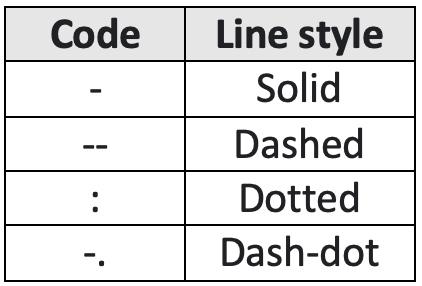   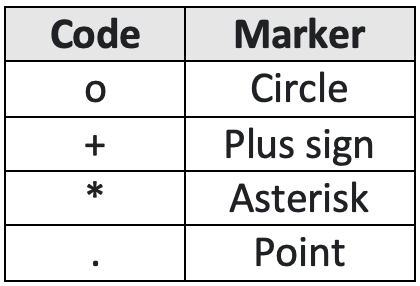    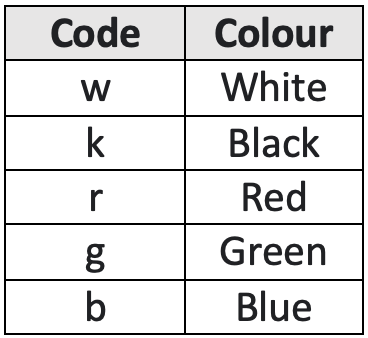

In this case, `'ro-'` creates the plot using the color `Red`, with marker `Circle` and line style `Solid`. For more details see: [`plot()`](https://au.mathworks.com/help/matlab/ref/plot.html).

### 2.1 MATLAB code for basic example

Now we are ready to compute $t_k$ and $y_k$ and plot them. Run this section to see the result of the following code:

t = zeros(1,10+1);
y = zeros(1,10+1);
t(1) = 0;
y(1) = 1;
dt = 0.2;
for k = 1:10
    t(k+1) = t(k) + dt;
    y(k+1) = y(k) + dt * (1 - exp(-4 * t(k)) - 2 * y(k));
end
plot(t, y,'ro-')
t(end) % or t(11)
y(end) % or y(11)

**Remark 3:** Observe that we added in the last two lines `t(end)` and `y(end)`. This gives you the last values from each array. More details here: [Last array index](https://au.mathworks.com/help/matlab/ref/end.html). You can easily access any other value by replacing `"end"` by any other integer from 1 to 10.

## 3 Advanced examples

### 3.1 Anonymous functions

An [anonymous function](https://au.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) is a function that is not written in an extermal file (usually named *M-file*), rather is associated with a [*function handle*](https://au.mathworks.com/help/matlab/ref/function_handle.html). Anonymous functions work as regular functions, accepting inputs and returning outputs. As an example to create an anonymous function with the handle `sqr` which squares a number. For example, run this section to see the output of the following code:

sqr = @(x) x.^2;
sqr(5)

In section 2.1 we used the expression

`(1 - exp(-4 * t(k)) - 2 * y(k))`

to define the ODE. This can be easily replaced by

`f(t(k), y(k))`

using the following anonymous function:

#### 3.1.1 Example with anonymous function

The same result from section 2.1 can be obtained with the following code:

clear % This command just removes variables to free memory

% Define anonymous function
f = @(t,y) 1 - exp(-4 * t) - 2 * y;

t = zeros(1,10+1);
y = zeros(1,10+1);
t(1) = 0;
y(1) = 1;
dt = 0.2;
for k = 1:10
    t(k+1) = t(k) + dt;
    y(k+1) = y(k) + dt * f(t(k), y(k)); % Here we use the anonymous function
end
plot(t, y, 'bo-')

Modify the anonymous function, try for example $f(t,y)=5t+y^2$ and re-run this section to see the result.

### 3.2 Pre-defined functions

We can also implement Euler's method by using pre-defined funcitons. In order to do that  we must create our own [MATLAB function](https://au.mathworks.com/help/matlab/ref/function.html)

In MATLAB we **must declare a new **[**function**](https://au.mathworks.com/help/matlab/ref/function.html) before using it in our code. In the case of **Live Scripts**, we can add it at the very end of our document, see [Appendix](https://www.dynamicmath.xyz/matlab/math1051/04-derivatives/DerivativesWorkshop.html#H_9D562ED3) for more details.

Using the pre-defined function named `my_euler`, we can easily compute as many values as we want with any given step size. In this case, `my_euler` function requires five inputs:

- `f` = anonymous function,

- `t_0` = initial value of $t$,

- `y_0` = initial value of $y$,

- `dt` = step size,

- `t_f` = final value of $t$.

#### 3.2.1 Example with pre-define function

Let's compute $y_k$ from $t=0$ to $t=2$ using the same ODE with a step size $\Delta t=0.05$. Run this section to see the result of the following code:

clear % This command just removes variables to free memory

% Define initial conditions and step size
t_0 = 0; 
y_0 = 1;
dt = 0.05;

% Define the last value 't' we want to compute
t_f = 2;

% Define anonymous function
f = @(t,y) 1 - exp(-4 * t) - 2 * y;

% Apply pre-define function
my_euler(f, t_0, y_0, dt, t_f);

Play around the previous code. Modify some parameters and re-run this section to see the changes.

## 4. Hands on Practice

Let's practice what we just learned.

#### **Activity 1:**

We know that the general solution of 

$\frac{dy}{dt}=1- e^{-4t}+2y$.

is given by

$y(t) = \frac{1}{2}+\frac{e^{-4t}}{2}+ke^{-2t}$.

Using the initial condition of the IVP, $y(0)=1$, we can easily determine the value for $k=0$ and hence the particular solution for this IVP. (You should check this is true in your notebook)

Compare the general solution with Euler's method for different values of $\Delta t$.

If you run this section, you will plot the general solution for $k=0$ over the domain $[0,2.5]$. Compare the general solution with Euler's method for the following values of the step size:

- 
$$\Delta t = 0.5$$


- 
$$\Delta t = 0.05$$


- 
$$\Delta t = 0.01$$


You can use any of the methods described above. Write your code in the indicated space below:

t = linspace(0, 2.5, 1000);      % 1000 points between 0 and 2.5
y = 1/2 + exp(-4 * t)/2;         % Define general solution
plot(t, y, '-k', 'LineWidth', 2) % plot general solution
hold on

%%% Your code must go after this line %%%




%%% Your code must go before this line %%%

hold off

**Remark 3:** To help us plot the general solution we are using the command [`linspace(x1, x2, n)`](https://au.mathworks.com/help/matlab/ref/linspace.html) which generates $n$ points between `x1` and `x2` (including the end points). The spacing between them is

`(x2-x1)/(n-1)`.

This command is similar to the colon operator "`:`", but gives direct control over the number of points and always includes the endpoints. 

#### **Activity 2**

Now consider the IVP

$\frac{dy}{dt}=5t-10$, $y(0)=1$.

In your notebook, calculate the exact solution. Then use Euler's method to approximate the solution for the following values:

- step size $\Delta t = 0.05$ and last value of $t=5$.

- step size $\Delta t = 0.1$ and last value of $t=5$.

What are the approximate values of $y(2)$ and $y(5)$ for $\Delta t=0.1$? And for $\Delta t=0.05$?Compare these values with those obtained using the exact solution.

Write your code here:

**Hint:** You can create an anonymous function for the expression $5t-10$. 

## Appendix: Pre-defined functions

function [ tval, yval ] = my_euler(f, t_0, y_0, dt, t_f)

% 'my_euler' function inputs: 
%     f = anonymous function
%     t_0 = initial value of t
%     y_0 = initial value of y
%     dt = step size
%     t_f = final value of t
% 'my_euler' outputs: 
%     plots (t, y) points

% Clear the 't' and 'y' variables
clear t y

% Calculate how many steps it takes to get from t_0 to t_f
nsteps = ceil((t_f -t_0)/dt);  
% To lear more about the ceil function check:
% https://au.mathworks.com/help/matlab/ref/ceil.html

% initialise the storage vectors.
t = zeros(1, nsteps + 1); 
y = zeros(1, nsteps + 1);
t(1) = t_0;
y(1) = y_0;
 
for k = 1:nsteps
    % calculate the next t-value
    t(k+1) = t(k) + dt; 
    % calculate the corresponding approximation for y
    y(k+1) = y(k) + dt * f(t(k), y(k));   
end

% Plot the solution with blue points
% and connected by red segments
plot(t, y,'bo', t, y,'r-', 'LineWidth', 2)  

xlabel('t')
ylabel('y')
 
% define the function outputs:
tval = t(end); % or t(nsteps+1)
yval = y(end); % or y(nsteps+1)
 
end